clear
clc
%% Load Dataset
Xtrain = load('Xtrain.mat').Xtrain;
Ytrain = load('Ytrain.mat').Ytrain;
Xtest = load('Xtest.mat').Xtest;
Ytest = load('Ytest.mat').Ytest;
cvKF5 = load('cvKF5.mat','cvKF5').cvKF5;
cvKF10 = load('cvKF10.mat','cvKF10').cvKF10;
cvKF20 = load('cvKF20.mat','cvKF20').cvKF20;
%% Load MRMR
MRMR = load('MRMR.mat').MRMR;
idxMRMR = MRMR(1,:);
scores = MRMR(2,:);
%% Random Forest


%% K vs Num. Features (K-Fold = 5)
Ks =[50:10:150];
rfMRMR_5 = zeros(12,length(Ks));
AUC_5 = zeros(12,length(Ks));
F1_5 = zeros(12,length(Ks));

for f=1:12
    for k=1:length(Ks)
        rfMRMR_CV = fitensemble(Xtrain(:,idxMRMR(1:12)),Ytrain, 'Bag', k, 'Tree', 'Type', 'classification', 'CVPartition', cvKF5);
        [rfMRMR_pred,scores] = kfoldPredict(rfMRMR_CV);
        rfMRMR_5(f,k) = mean(Ytrain == rfMRMR_pred);
        
        [~,~,~,AUCrf_n] = perfcurve(Ytrain,scores(:,1),'Necrosis');
        [~,~,~,AUCrf_s] = perfcurve(Ytrain,scores(:,2),'Stroma');
        [~,~,~,AUCrf_t] = perfcurve(Ytrain,scores(:,3),'Tumor');
        AUC_5(f,k) = (AUCrf_n + AUCrf_s + AUCrf_t)/3;
        tpNk = sum(ismember(Ytrain,'Necrosis') & ismember(rfMRMR_pred,'Necrosis'));
        tpSk = sum(ismember(Ytrain,'Stroma') & ismember(rfMRMR_pred,'Stroma'));
        tpTk = sum(ismember(Ytrain,'Tumor') & ismember(rfMRMR_pred,'Tumor'));
        fpNk = sum(ismember(rfMRMR_pred,'Necrosis')) - tpNk;
        fpSk = sum(ismember(rfMRMR_pred,'Stroma')) - tpSk;
        fpTk = sum(ismember(rfMRMR_pred,'Tumor')) - tpTk;
        fnNk = sum(ismember(Ytrain, 'Necrosis')) - tpNk;
        fnSk = sum(ismember(Ytrain, 'Stroma')) - tpSk;
        fnTk = sum(ismember(Ytrain, 'Tumor')) - tpTk;
        f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
        f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
        f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);
        F1_5(f,k) = (f1Nk + f1Sk + f1Tk)/3;

        
    end
end
%% Heatmap Accuracy
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
figure;
h5 = heatmap(xvals_numF, yvals_k, rfMRMR_5, 'Colormap', jet, 'CellLabelColor','none');
title('Accruacy 5-Fold');
h5.XLabel = 'K_R_F';
h5.YLabel = 'Num of Features';

%% Heatmap AUC
figure;
h = heatmap(xvals_numF, yvals_k, AUC_5, 'Colormap', jet, 'CellLabelColor','none');
title('AUC 5-Fold');
h.XLabel = 'K_R_F';
h.YLabel = 'Num of Features';
%% Heatmap F1
figure;
h = heatmap(xvals_numF, yvals_k,F1_5, 'Colormap', jet, 'CellLabelColor','none');
title('F1 Score 5-Fold');
h.XLabel = 'K_R_F';
h.YLabel = 'Num of Features';


figure;
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
subplot(3,1,1);
heatmap(xvals_numF, yvals_k, rfMRMR_5,'Colormap', jet, 'CellLabelColor','none');
title('Random Forest: Accruacy 5-Fold');
h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';
subplot(3,1,2);
heatmap(xvals_numF, yvals_k, AUC_5,'Colormap', jet, 'CellLabelColor','none');
title('Random Forest: AUC 5-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';
subplot(3,1,3);
heatmap(xvals_numF, yvals_k,F1_5,'Colormap', jet, 'CellLabelColor','none');
title('Random Forest: F1 Score 5-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

## K vs Num. Features (K-Fold = 10)


Ks =[50:10:150];
rfMRMR_10 = zeros(12,length(Ks));
AUC_10 = zeros(12,length(Ks));
F1_10 = zeros(12,length(Ks));

for f=1:12
    for k=1:length(Ks)
        rfMRMR_CV = fitensemble(Xtrain(:,idxMRMR(1:12)),Ytrain, 'Bag', k, 'Tree', 'Type', 'classification', 'CVPartition', cvKF10);
        [rfMRMR_pred,scores] = kfoldPredict(rfMRMR_CV);
        rfMRMR_10(f,k) = mean(Ytrain == rfMRMR_pred);
        
        [~,~,~,AUCrf_n] = perfcurve(Ytrain,scores(:,1),'Necrosis');
        [~,~,~,AUCrf_s] = perfcurve(Ytrain,scores(:,2),'Stroma');
        [~,~,~,AUCrf_t] = perfcurve(Ytrain,scores(:,3),'Tumor');
        AUC_10(f,k) = (AUCrf_n + AUCrf_s + AUCrf_t)/3;
        tpNk = sum(ismember(Ytrain,'Necrosis') & ismember(rfMRMR_pred,'Necrosis'));
        tpSk = sum(ismember(Ytrain,'Stroma') & ismember(rfMRMR_pred,'Stroma'));
        tpTk = sum(ismember(Ytrain,'Tumor') & ismember(rfMRMR_pred,'Tumor'));
        fpNk = sum(ismember(rfMRMR_pred,'Necrosis')) - tpNk;
        fpSk = sum(ismember(rfMRMR_pred,'Stroma')) - tpSk;
        fpTk = sum(ismember(rfMRMR_pred,'Tumor')) - tpTk;
        fnNk = sum(ismember(Ytrain, 'Necrosis')) - tpNk;
        fnSk = sum(ismember(Ytrain, 'Stroma')) - tpSk;
        fnTk = sum(ismember(Ytrain, 'Tumor')) - tpTk;
        f1Nk = tpNk/(tpNk + (fpNk+fnNk)/2);
        f1Sk = tpSk/(tpSk + (fpSk+fnSk)/2);
        f1Tk = tpTk/(tpTk + (fpTk+fnTk)/2);
        F1_10(f,k) = (f1Nk + f1Sk + f1Tk)/3;
    end
end
%% Heatmap Accuracy
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
figure;
h5 = heatmap(xvals_numF, yvals_k, rfMRMR_10, 'Colormap', jet, 'CellLabelColor','none');
title('Random Forest - Accuracy');
h5.XLabel = 'K_R_F';
h5.YLabel = 'Num of Features';
%% Heatmap AUC
figure;
h2 = heatmap(xvals_numF, yvals_k, AUC_10, 'Colormap', jet, 'CellLabelColor','none');
title('Random Forest - AUC');
h2.XLabel = 'K_R_F';
h2.YLabel = 'Num of Features';
%% Heatmap F1
figure;
h = heatmap(xvals_numF, yvals_k,F1_10, 'Colormap', jet, 'CellLabelColor','none');
title('Random Forest - F1 Score');
h.XLabel = 'K_R_F';
h.YLabel = 'Num of Features';


figure;
xvals_numF = num2cell(Ks);
yvals_k = num2cell([1:12]);
subplot(3,1,1);
heatmap(xvals_numF, yvals_k, rfMRMR_10,'Colormap', jet, 'CellLabelColor','none');
title('Random Forest: Accruacy 10-Fold');
h5.XLabel = 'K_K_N_N';
h5.YLabel = 'Num of Features';
subplot(3,1,2);
heatmap(xvals_numF, yvals_k, AUC_10,'Colormap', jet, 'CellLabelColor','none');
title('Random Forest: AUC 10-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';
subplot(3,1,3);
heatmap(xvals_numF, yvals_k,F1_10,'Colormap', jet, 'CellLabelColor','none');
title('Random Forest: F1 Score 10-Fold');
h.XLabel = 'K_K_N_N';
h.YLabel = 'Num of Features';

## External Validtion


rfMRMR_flat_1 = reshape(rfMRMR_10,[],1);
rfMRMR_flat = sort(unique(rfMRMR_flat_1), 'descend');
fk = [];
rfMRMR_CV_preds = [];
%%%%%%%%%%%%%%%%%%%%Different feature num: Choose 3 features out of 7
for a=1:3
    inds = find(rfMRMR_10 == rfMRMR_flat(a));
    for i = 1:length(inds)
        [f,k] = ind2sub(size(rfMRMR_10),inds(i));
        fk = [fk; f, k];
        rfMRMR_CV_preds = [rfMRMR_CV_preds, rfMRMR_flat(a)];
    end
end
%%
rfMRMR_preds = [];
for i=1:length(fk)
    f = fk(i,1);
    k = fk(i,2);
    disp(Ks(k))
    rfMRMR_CV = fitensemble(Xtrain(:,idxMRMR(1:f)),Ytrain, 'Bag', Ks(k), 'Tree', 'Type', 'classification');
    pred = predict(rfMRMR_CV, Xtest(:,idxMRMR(1:f)));
    rfMRMR_preds = [rfMRMR_preds, mean(pred==Ytest)]; % accuracy
    
end


## Plot Acuracy

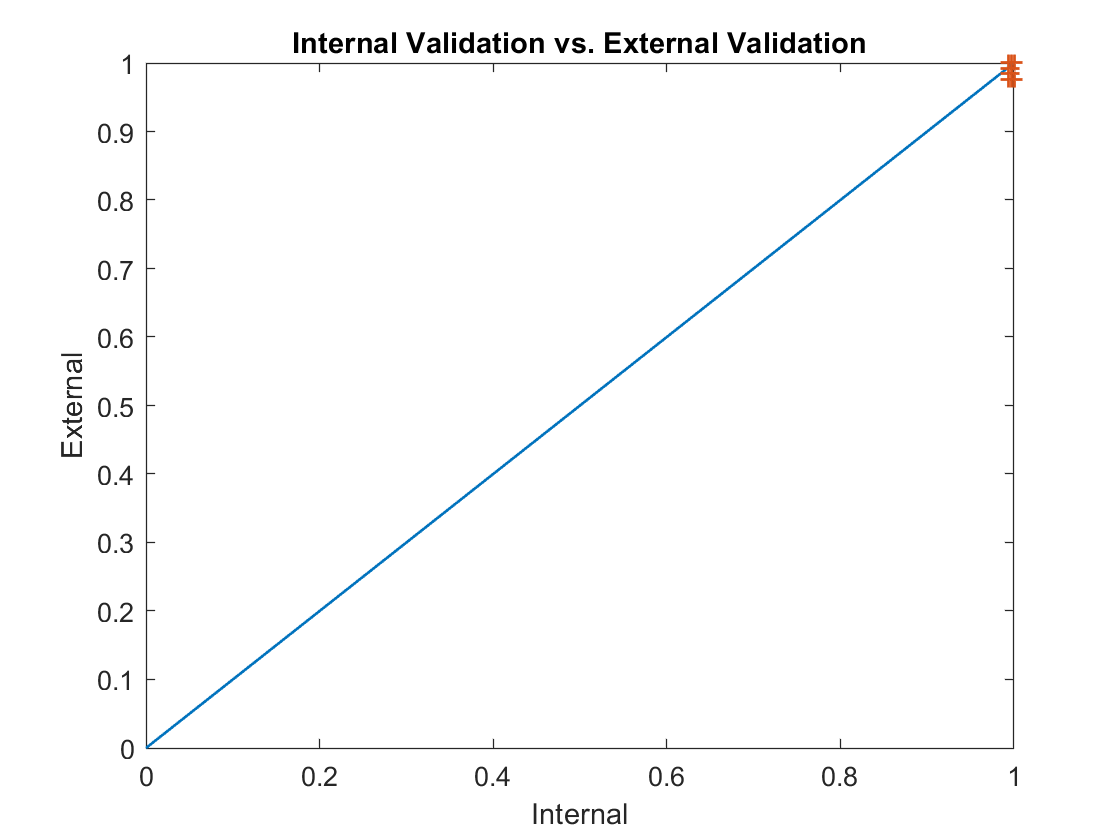


figure;
x = [0:1];
y = x;
plot(x, y,'Linewidth',1);
hold on

scatter(rfMRMR_CV_preds,rfMRMR_preds,'+','Linewidth',1);

xlabel('Internal');
ylabel('External');
title('Internal Validation vs. External Validation');


save("rfMRMR_preds.mat","rfMRMR_preds");
save("rfMRMR_CV_preds.mat","rfMRMR_CV_preds");
%%
% 9, 90
master_rf = [rfMRMR_preds.', fk];
master_rf = sortrows(master_rf,1,'descend');
bf = master_rf(1,2);
bk = Ks(master_rf(1,3));
rfMRMR = fitensemble(Xtrain(:,idxMRMR(1:9)),Ytrain, 'Bag', 90, 'Tree', 'Type', 'classification');
[pred,score] = predict(rfMRMR, Xtest(:,idxMRMR(1:9)));
acc = mean(pred==Ytest) * 100 % accuracy
figure;
cm = confusionchart(cellstr(Ytest),pred);
title(['Random Forest: ', num2str(acc), '%'])


figure;
subplot(2,1,1);
x = [0:1];
y = x;
plot(x, y,'Linewidth',1);
hold on

scatter(rfMRMR_CV_preds,rfMRMR_preds,'+','Linewidth',1);

xlabel('Internal');
ylabel('External');
title('Internal Validation vs. External Validation');
master_rf = [rfMRMR_preds.', fk];
master_rf = sortrows(master_rf,1,'descend');
bf = master_rf(1,2);
bk = Ks(master_rf(1,3));
rfMRMR = fitensemble(Xtrain(:,idxMRMR(1:9)),Ytrain, 'Bag', 90, 'Tree', 'Type', 'classification');
[pred,score] = predict(rfMRMR, Xtest(:,idxMRMR(1:9)));
acc = mean(pred==Ytest) * 100 % accuracy
subplot(2,1,2);
confusionchart(cellstr(Ytest),pred);
title(['Random Forest: ', num2str(acc), '%'])


## AUC


[X_rf_n,Y_rf_n,T,AUCrf_n] = perfcurve(Ytest,score(:,1),'Necrosis');
[X_rf_s,Y_rf_s,T,AUCrf_s] = perfcurve(Ytest,score(:,2),'Stroma');
[X_rf_t,Y_rf_t,T,AUCrf_t] = perfcurve(Ytest,score(:,3),'Tumor');

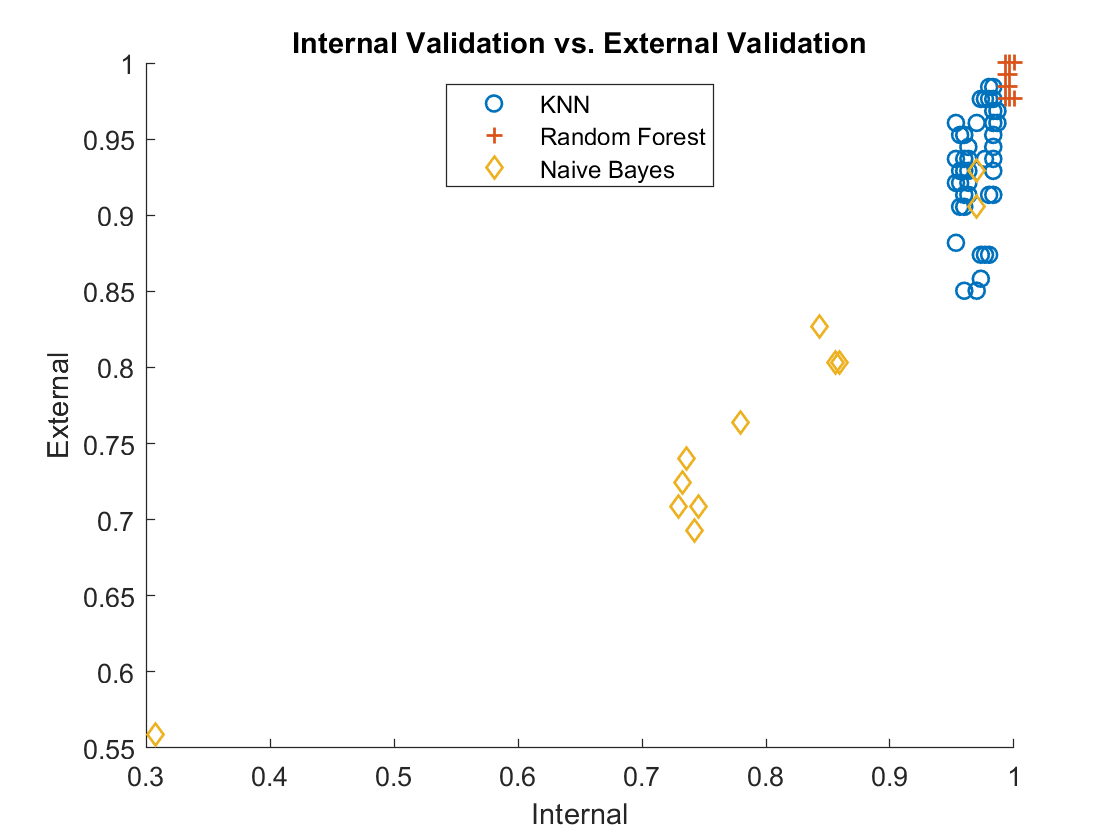

figure;
scatter(knnMRMR_CV_preds,knnMRMR_preds,'o','Linewidth',1);
hold on
scatter(rfMRMR_CV_preds,rfMRMR_preds,'+','Linewidth',1);
hold on
scatter(nbMRMR_CV_preds,nbMRMR_preds,'d','Linewidth',1);
xlabel('Internal');
ylabel('External');
legend('KNN','Random Forest','Naive Bayes','Location','north');
title('Internal Validation vs. External Validation');